optimParams_v1

Optim Params by using Surrogate optimization for an expensive optimization problems

% Load data
% load pricevolumedata.mat ;
dataInput = load("pricevolumedata.mat")

dataInput = struct with fields:
    closepriceTT: [1212×665 timetable]
     highpriceTT: [1212×665 timetable]
      indexclean: [1212×6 timetable]
      lowpriceTT: [1212×665 timetable]
     openpriceTT: [1212×665 timetable]
        volumeTT: [1212×665 timetable]


% Test objective and constraints function
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = [70	106	5	3	8	14	107	29	4	4	6]

paramsInput =     70   106     5     3     8    14   107    29     4     4     6


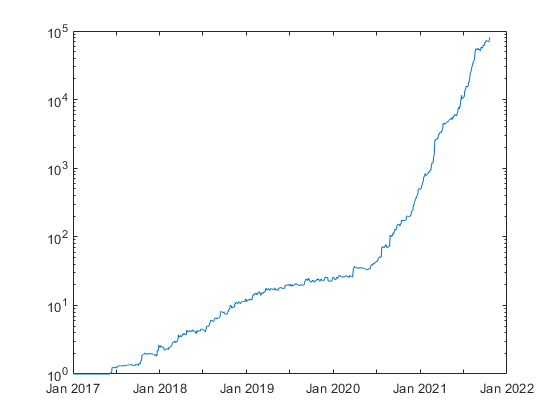

portEndValue = 8.1092e+04

portMinValue = 1

portMaxValue = 8.1092e+04

MaxDD = 0.1617

MaxDDIndex =    253
   271


drawdownDate = 2×1 datetime array
   2017-12-28
   2018-01-23


sharpeRatio = 4.7270

FortValueAtOptPoint = 7.0633e+04

PortRetOptPtEnd = 0.1481

optimPointDate = datetime
   2021-10-13


nYear = 4.8027

CAGR = 9.5225

dailyRetAvg = 0.0099

dailyRetMin = -0.1234

dailyRetMax = 0.3212

symCumRetEndT = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'FIRE'}       {[1.5618]}    
    {'TCPI'}       {[1.5249]}    
    {'INAF'}       {[1.4953]}    
    {'BBHI'}       {[1.4539]}    
    {'BNBA'}       {[1.3930]}    
    {'KAEF'}       {[1.3420]}    
    {'ACST'}       {[1.3167]}    
    {'ABBA'}       {[1.3013]}    
    {'MTWI'}       {[1.2918]}    
    {'BOLA'}       {[1.2735]}    
    {'MPPA'}       {[1.2411]}    
    {'SURE'}       {[1.2349]}    
    {'FILM'}       {[1.2328]}    
    {'ZBRA'}       {[1.2217]}    
    {'RAJA'}       {[1.2210]}    
    {'FREN'}       {[1.2186]}    


CAGR = 9.5225

tradingSignalTT = tradingSignalFcnVectorized_v1 (paramsInput, dataInput) ;
[portDailyRetTT, netDailyRetperSymTT] = tradingBacktestFcn_v2 (tradingSignalTT, dataInput) ;

CAGR = analyzeTradeResults (dataInput, tradingSignalTT, portDailyRetTT, netDailyRetperSymTT, optimPoint)

Optim parameters

Define upper, lower bound and constraints

startTime = tic

startTime = uint64
1692652005768

% Define upper, lower and bound 
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
lb              = [20   50  5   1   3   2   80  10  1   1   0] ;
ub              = [150  150 60  6   20  30  250 60  10  8   15] ;

% lb              = [60   50  5   1  2   0   60  5   3   1   0] ;
% ub              = [250  200 60  10 10  15  250 30  5   5   8] ;

% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 


% Integer constraints
nvars = 11 ;
intcon = 1:nvars ;

% Objective & constraints function
optimPoint = 5

optimPoint = 5

dataInput = load("pricevolumedata.mat") ;

% f =  @(x)objconstrFcn(x, dataInput, optimPoint);
% f =  @(x)objFcn(x, dataInput, optimPoint);
obj = @(x)objFcn(x, dataInput, optimPoint) ;
nlconst = @(x)nlconstFcn(x, dataInput, optimPoint) ;

objconstr = packfcn(obj,nlconst) ;
f = objconstr ;

% Set options
maxFcnEval = 600;
opts = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-4, "MaxFunctionEvaluations",maxFcnEval, ...
    "UseParallel", true, "UseVectorized",true);


Call `surrogateopt` to solve the problem

Objective or constraint function returned NaN.


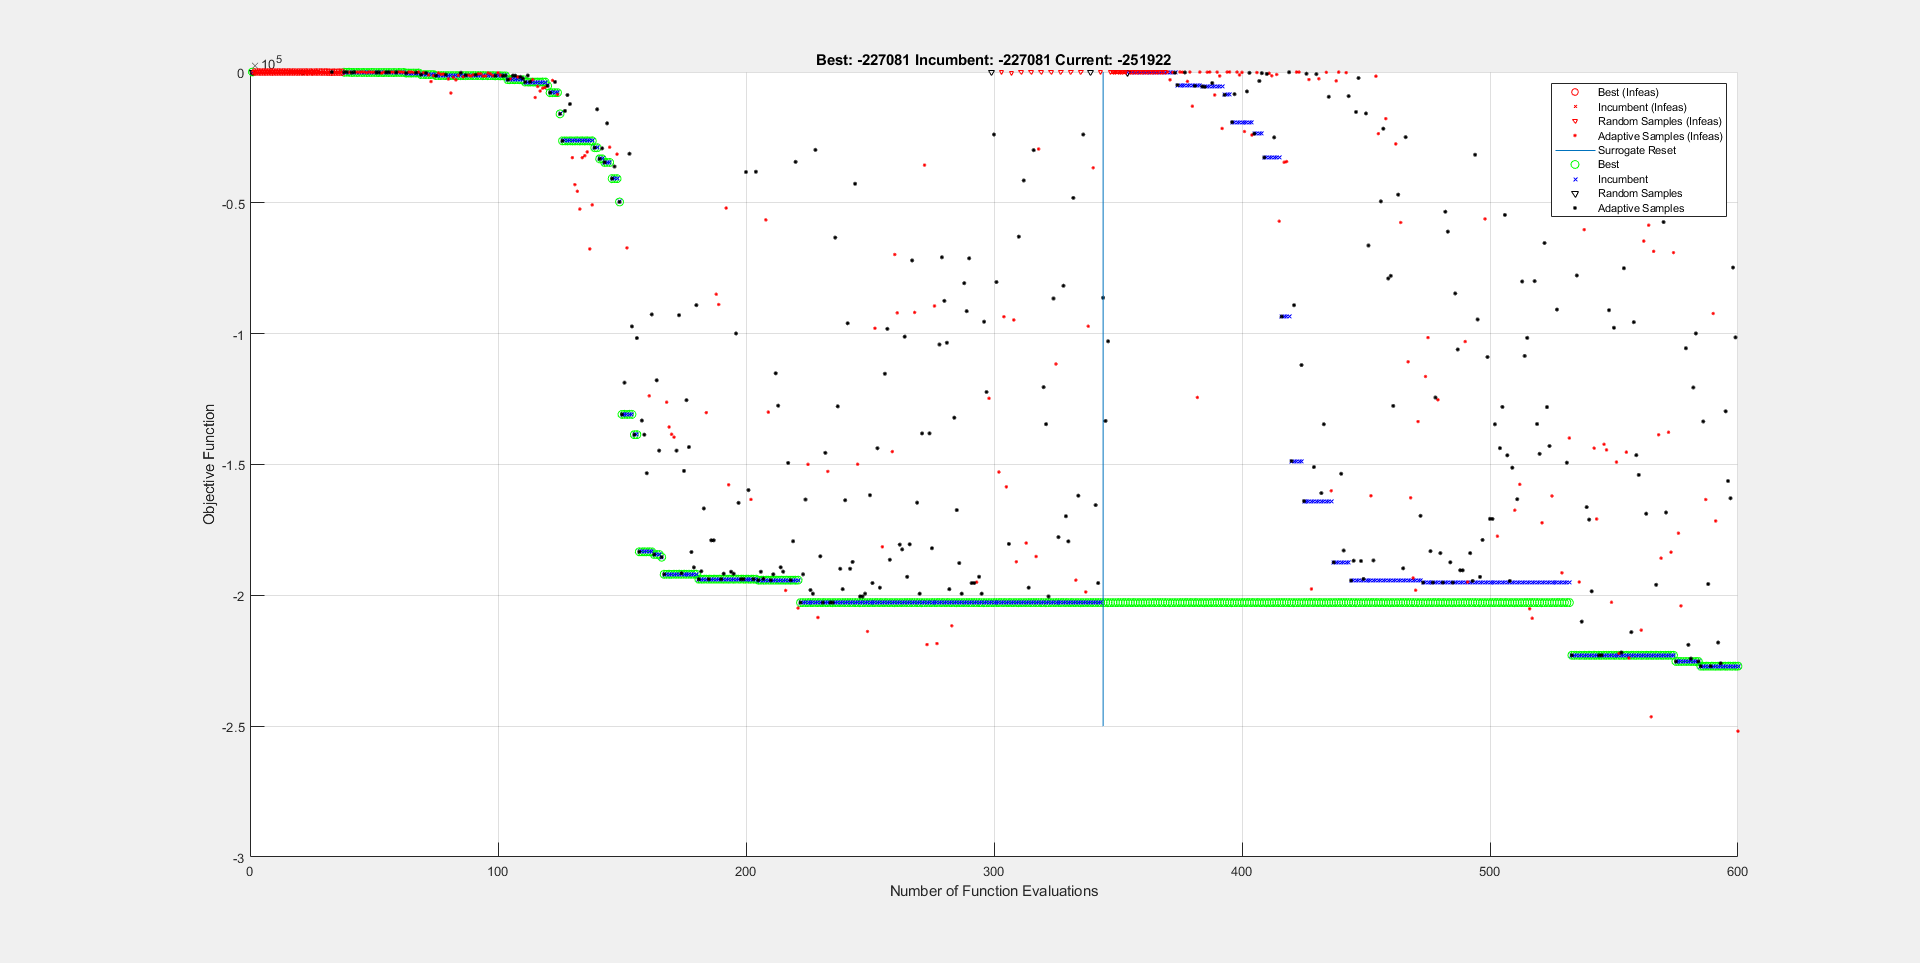

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     54    79     5     1     4     2   123    15     3     2     4


fval = -2.2708e+05

exitflag = 0

outpt = struct with fields:
        elapsedtime: 739.3620
          funccount: 600
    constrviolation: -0.0084
               ineq: [-0.0084 -2.2370]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


% Call surrogateopt to solve the problem
% rng default % For reproducibility
[sol,fval,exitflag,outpt] = surrogateopt(f,lb,ub,intcon,opts)


endTime = toc(startTime)

endTime = 741.2435

Examine result of optimized params

paramsInput     = sol

paramsInput =     54    79     5     1     4     2   123    15     3     2     4


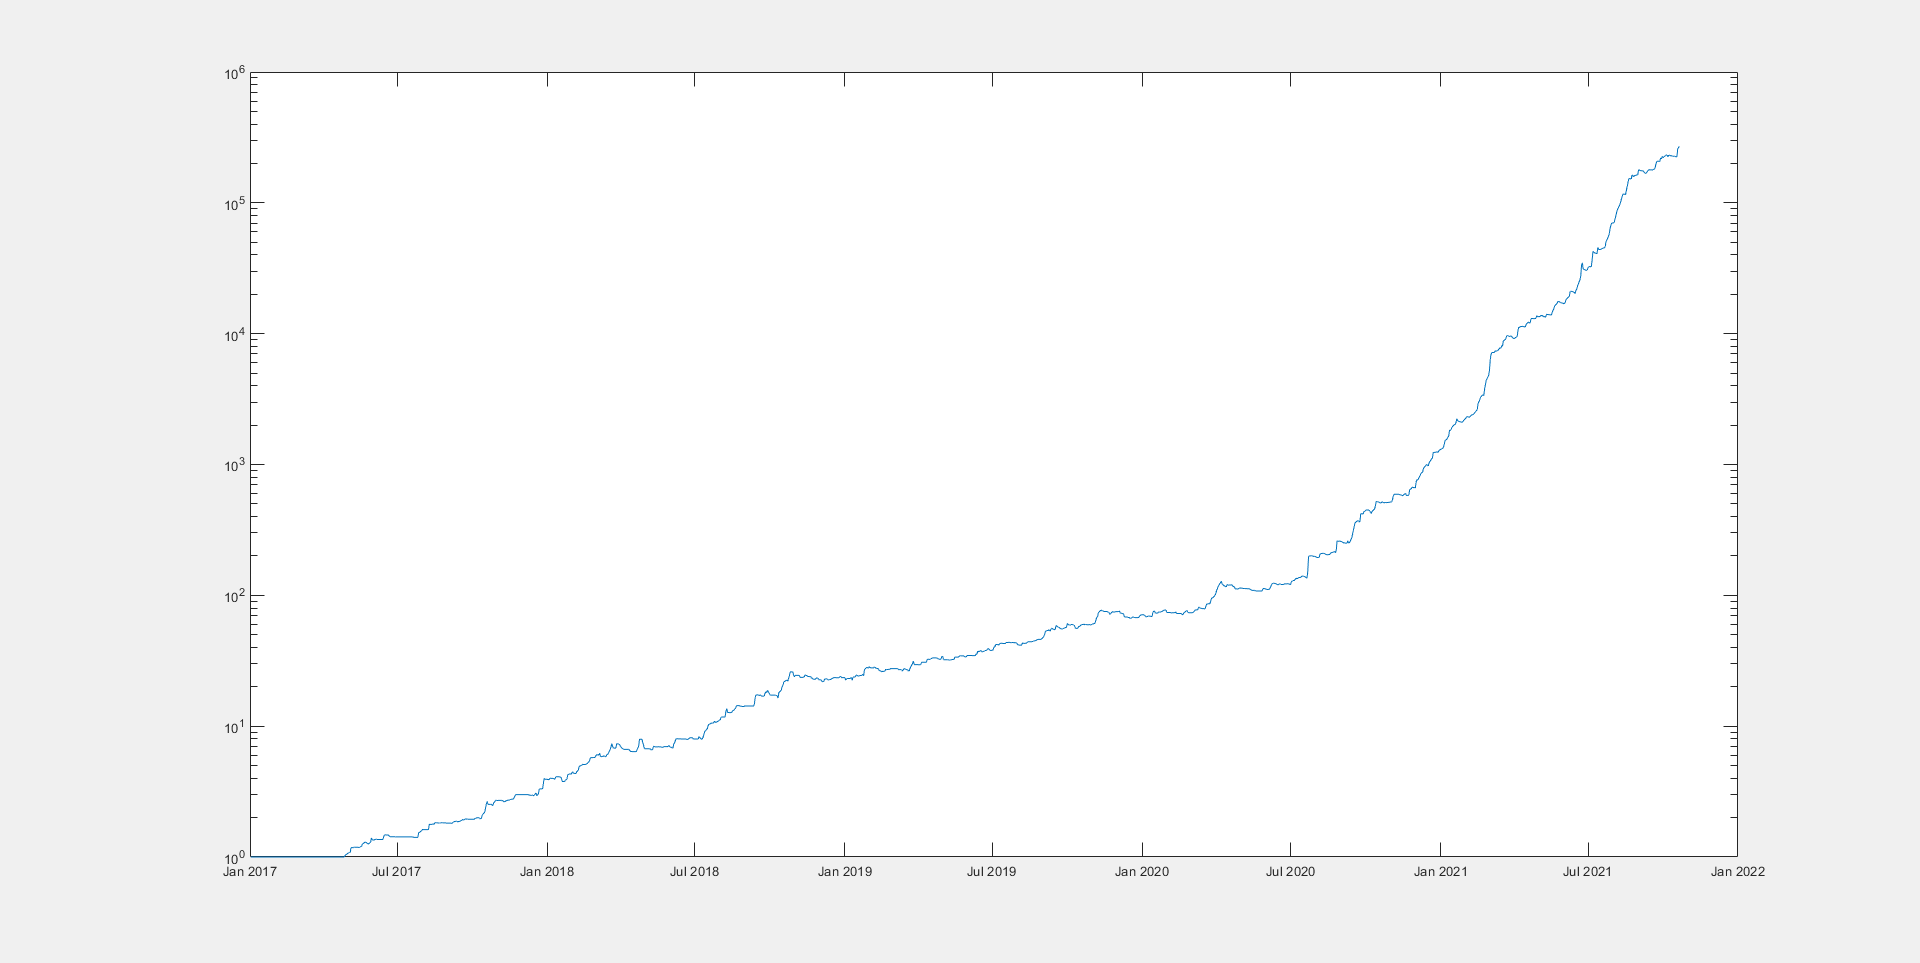

portEndValue = 2.7062e+05

portMinValue = 1

portMaxValue = 2.7062e+05

MaxDD = 0.1716

MaxDDIndex =    336
   348


drawdownDate = 2×1 datetime array
   2018-04-24
   2018-05-10


sharpeRatio = 5.2370

FortValueAtOptPoint = 2.2708e+05

PortRetOptPtEnd = 0.1917

optimPointDate = datetime
   2021-10-13


nYear = 4.8027

CAGR = 12.5237

dailyRetAvg = 0.0109

dailyRetMin = -0.1521

dailyRetMax = 0.3185

symCumRetEndT = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'TCPI'}       {[1.4875]}    
    {'ZBRA'}       {[1.4458]}    
    {'BNBA'}       {[1.3520]}    
    {'ACST'}       {[1.3077]}    
    {'MTWI'}       {[1.2751]}    
    {'INAF'}       {[1.2697]}    
    {'ABBA'}       {[1.2641]}    
    {'KAEF'}       {[1.2618]}    
    {'BOLA'}       {[1.2466]}    
    {'PADI'}       {[1.2391]}    
    {'SURE'}       {[1.2349]}    
    {'FILM'}       {[1.2260]}    
    {'TECH'}       {[1.2226]}    
    {'BBHI'}       {[1.2218]}    
    {'FIRE'}       {[1.2198]}    
    {'BBYB'}       {[1.2059]}    


CAGR = 12.5237

tradingSignalTT = tradingSignalFcnVectorized_v1 (paramsInput, dataInput) ;
[portDailyRetTT, netDailyRetperSymTT] = tradingBacktestFcn_v2 (tradingSignalTT, dataInput) ;

CAGR = analyzeTradeResults (dataInput, tradingSignalTT, portDailyRetTT, netDailyRetperSymTT, optimPoint)

Analyze the input parameters compared to its boundaries

% Examine result of optimized params
% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 

% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
counterhelp     = [1    2   3   4   5   6   7   8   9   10  11]

counterhelp =      1     2     3     4     5     6     7     8     9    10    11


sol

sol =     54    79     5     1     4     2   123    15     3     2     4


lb              = [20   50  5   1   3   2   80  10  1   1   0] 

lb =     20    50     5     1     3     2    80    10     1     1     0


ub              = [150  150 60  6   20  30  250 60  10  8   15] 

ub =    150   150    60     6    20    30   250    60    10     8    15


Stock picks

% Stock picks

stockpicks
